% mikexcohen@gmail.com

## show Gaussian with different number of cycles

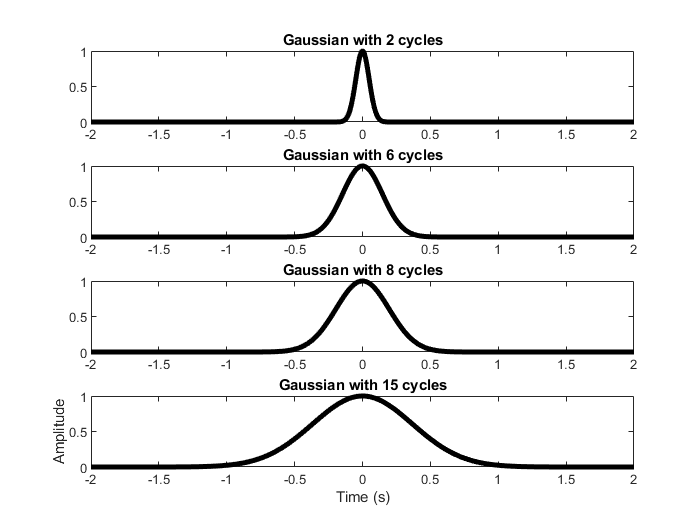

load sampleEEGdata.mat

% set a few different wavelet widths ("number of cycles" parameter)
num_cycles = [ 2 6 8 15 ];
frex = 6.5;

time = -2:1/EEG.srate:2;

figure(1), clf
for i=1:4
    subplot(4,1,i)
    s = num_cycles(i) / (2*pi*frex);
    plot(time, exp( (-time.^2) ./ (2*s^2) ),'k','linew',3)
    title([ 'Gaussian with ' num2str(num_cycles(i)) ' cycles' ])
end

xlabel('Time (s)'), ylabel('Amplitude')

## show frequency spectrum of wavelets with different number of cycles

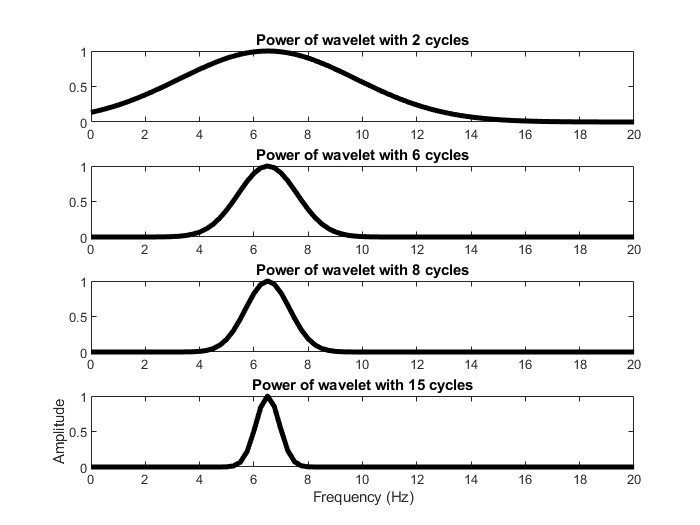

figure(2), clf
for i=1:4
    subplot(4,1,i)
    s = num_cycles(i) / (2*pi*frex);
    cmw = exp(1i*2*pi*frex.*time) .* exp( (-time.^2) ./ (2*s^2) );
    
    % take its FFT
    cmwX = fft(cmw);
    cmwX = cmwX./max(cmwX);
    hz = linspace(0,EEG.srate/2,floor(length(time)/2)+1);
    
    % plot it
    plot(hz,abs(cmwX(1:length(hz))),'k','linew',3)
    set(gca,'xlim',[0 20])
    title([ 'Power of wavelet with ' num2str(num_cycles(i)) ' cycles' ])
end

xlabel('Frequency (Hz)'), ylabel('Amplitude')

## comparing fixed number of wavelet cycles

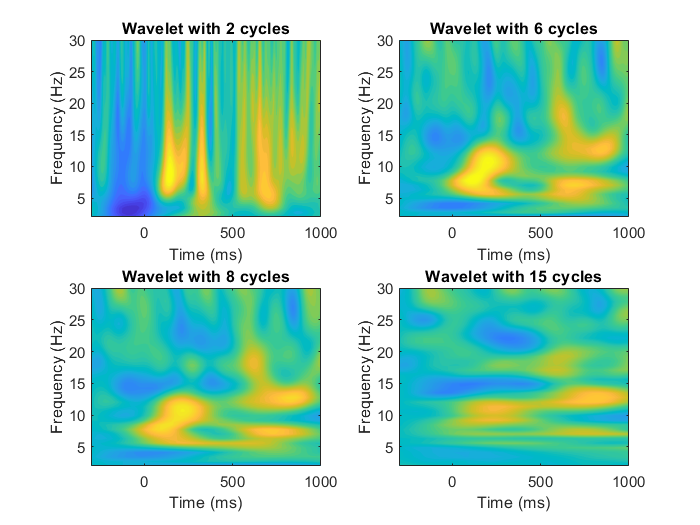

% wavelet parameters
num_frex = 40;
min_freq =  2;
max_freq = 30;

channel2use = 'o1';

baseline_window = [ -500 -200 ];

% set a few different wavelet widths ("number of cycles" parameter)
num_cycles = [ 2 6 8 15 ];

% other wavelet parameters
frex = linspace(min_freq,max_freq,num_frex);
time = -2:1/EEG.srate:2;
half_wave = (length(time)-1)/2;

% FFT parameters
nKern = length(time);
nData = EEG.pnts*EEG.trials;
nConv = nKern+nData-1;

% initialize output time-frequency data
tf = zeros(length(num_cycles),length(frex),EEG.pnts);

% convert baseline time into indices
[~,baseidx(1)] = min(abs(EEG.times-baseline_window(1)));
[~,baseidx(2)] = min(abs(EEG.times-baseline_window(2)));


% FFT of data (doesn't change on frequency iteration)
dataX = fft(reshape(EEG.data(strcmpi(channel2use,{EEG.chanlocs.labels}),:,:),1,[]),nConv);

% loop over cycles
for cyclei=1:length(num_cycles)
    
    for fi=1:length(frex)
        
        % create wavelet and get its FFT
        s = num_cycles(cyclei)/(2*pi*frex(fi));
        
        cmw  = exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*s^2));
        cmwX = fft(cmw,nConv);
        cmwX = cmwX./max(cmwX);
        
        % run convolution, trim edges, and reshape to 2D (time X trials)
        as = ifft(cmwX .* dataX); % FT之後的wavelet與data相乘，最後再IFT
        as = as(half_wave+1 : end-half_wave); % trim edges
        as = reshape(as, EEG.pnts, EEG.trials); % reshape to 2D (time X trials)
        
        % put power data into big matrix
        tf(cyclei,fi,:) = mean(abs(as).^2,2);
    end
    
    % db conversion
    tf(cyclei,:,:) = 10*log10( bsxfun(@rdivide, squeeze(tf(cyclei,:,:)), mean(tf(cyclei,:,baseidx(1):baseidx(2)),3)' ) );
    
end

% plot results
figure(3), clf
for cyclei=1:length(num_cycles)
    subplot(2,2,cyclei)
    
    contourf(EEG.times,frex,squeeze(tf(cyclei,:,:)),40,'linecolor','none')
    set(gca,'clim',[-3 3],'ydir','normal','xlim',[-300 1000])
    title([ 'Wavelet with ' num2str(num_cycles(cyclei)) ' cycles' ])
    xlabel('Time (ms)'), ylabel('Frequency (Hz)')
end

## variable number of wavelet cycles

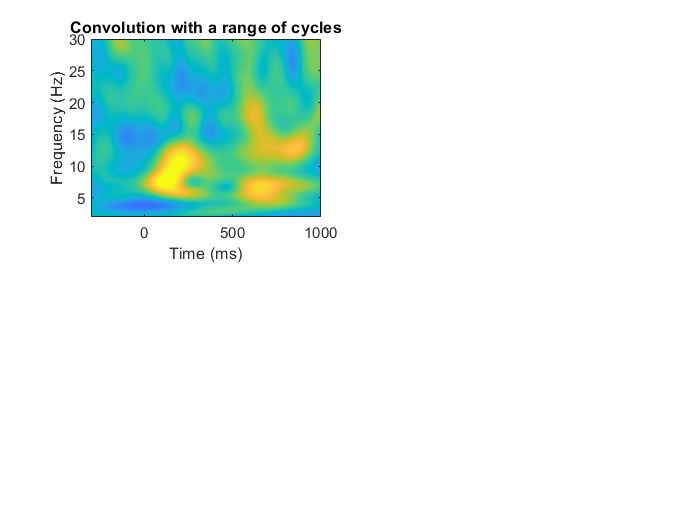

% set a few different wavelet widths (number of wavelet cycles)
range_cycles = [ 4 10 ];

% other wavelet parameters
nCycles = logspace(log10(range_cycles(1)),log10(range_cycles(end)),num_frex);

% initialize output time-frequency data
tf = zeros(length(frex),EEG.pnts);

for fi=1:length(frex)
    
    % create wavelet and get its FFT
    s = nCycles(fi)/(2*pi*frex(fi));
    cmw = exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*s^2));
    
    cmwX = fft(cmw,nConv);
    
    % run convolution
    as = ifft(cmwX.*dataX,nConv);
    as = as(half_wave+1:end-half_wave);
    as = reshape(as,EEG.pnts,EEG.trials);
    
    % put power data into big matrix
    tf(fi,:) = mean(abs(as).^2,2);
end

% db conversion
tf = 10*log10( bsxfun(@rdivide, tf, mean(tf(:,baseidx(1):baseidx(2)),2)) );

% plot results
figure(4), clf
subplot(2,2,1)

contourf(EEG.times,frex,tf,40,'linecolor','none')
set(gca,'clim',[-3 3],'ydir','normal','xlim',[-300 1000])
title('Convolution with a range of cycles')
xlabel('Time (ms)'), ylabel('Frequency (Hz)')

## end